# Exercici 1- Parcial- Ariadna Cortés Danés

**(a) **Escriure el codi per la matriu A i el vector b. Verifiqueu que X=(5,5,…,5)t és la solució del sistema de equacions AX=b

% Construcció de la matriu A i el  vector b
A = zeros(100,100);
A(1,1:2) = [8, -2];
for ii = 2: 99
    A(ii,ii-1:ii+1) = [-2 8 -2];
end
A(100,99:100) = [-2, 8]

A =      8    -2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    -2     8    -2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -2     8    -2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -2     8    -2     0     0     0     0     0     0     0     0     0     0   


b = 20*ones(100,1);
b(1) = 30;
b(100) = 30;
b'

ans =     30    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20



% Comprovació de que (5,5,...5) es solucio
x = 5*ones(100,1);
residu = norm(A*x - b,'inf')

residu =      0


% el residu es 0 per tant x és solució

** Resposta  **Calculeu per  X=(5,5,…,5)t�=(5,5,…,5)� el valor del residu r=||AX−b||

**(b1) **Determineu el radi espectral de la matriu de iteració del mètode de Jacobi per la resolució del sistema de equacions lineals AX=b��=� per A� i b� donats en l'enunciat.  

% radi espectral per jacobi
D = diag(diag(A));
d = diag(1./diag(A));    %D^(-1)
L = tril(A,-1);
U = triu(A,1);

Bj = -d*(L+U); c = d*b;
rhoJ = abs(eigs(Bj,1))    % no convergeix perque rhoJ > 1

rhoJ =    0.499758141145993



% el radi espectral es menor que 1 i per tant convergirà

**Resposta**  ρ= 0.4998 

**(b2) **Determineu el valor de ω òptim per a l'algorisme del mètode SOR (pàg. 67 apunts teoria) de resolució del sistema de equacions lineals AX=b per A i b donats en l'enunciat.

**Resposta** ω0= i ρ(Bω0) = 

w0 = 2/(1 + sqrt(1- rhoJ^2)) 

w0 =    1.071716597539942


rhoBw0 = w0 -1

rhoBw0 =    0.071716597539942


**(c) **Determineu la solució aproximada X⋆ del sistema AX=b amb un mínim de 12 decimals correctes pel métode iteratiu SOR (pàg. 64) apunts teoria. Quin vector X0 inicial preneu?

C = D^(-1); % matriu auxiliar
Bsor = C*((1 - w0)*D - w0*(L + U)); % Matriu d%iteració.
csor = w0*C*b;

r = [1];
k = 0;
x = zeros(size(b));         % vector inicial [0,0 ... 0]
while (r(end) > 10e-12)     % minim 12 decimals correctes
    x = Bsor*x + csor;
    r =[r norm(b - A*x,'inf')];
    k = k+1;
end
residu = r(end)   % residu

residu =      6.913580818945775e-12


x                 % solució trobada

x =    4.999999999999855
   5.000000000000278
   4.999999999999606
   5.000000000000485
   4.999999999999453
   5.000000000000577
   4.999999999999419
   5.000000000000557
   4.999999999999485
   5.000000000000458


k                 % iteracions necessaries

k =     48


**Resposta **Residuo: ||r||∞=    6.9e-12             i iteracions necessàries: k=.48.     

**(d) **Calculeu els valors δk=||Xk−X(k−1)||∞ i els valors ρk=δk/δk−1 si Xk és  el valor calculat pel mètode iteratiu SOR en la iteració k, (k>1).  

Representeu gràficament els valors ρk i verifiqueu en la gràfica la convergència de la sucesió de valors ρk al valor del radi espectral del mètode iteratiu de Jacobi. 

deltak = r(2:end) - r(1:end-1)

deltak =   10.962125518450438  -6.935714851134707  -2.834297068653077  -1.182963429468025  -0.531493392081963  -0.258143914492383  -0.113323457639833  -0.055928035381275  -0.025617937118142  -0.012647613704360  -0.005961711498927  -0.003012459664738  -0.001454882470885  -0.000758629744759  -0.000376936674105  -0.000201933087535  -0.000104164680206  -0.000056578659301  -0.000030590654990  -0.000016571432035  -0.000009453819427  -0.000005033012901  -0.000003037500644  -0.000001572848252  -0.000001003352679  -0.000000502418064  -0.000000331158802  -0.000000169791992  -0.000000109642983  -0.000000059199088  -0.000000036672802  -0.000000020763764  -0.000000012362353  -0.000000007308770  -0.000000004193172  -0.000000002545356  -0.000000001462414  -0.000000000885326  -0.000000000514913  -0.000000000309107  -0.000000000181160  -0.000000000108233  -0.000000000063743  -0.000000000037979  -0.000000000022439  -0.000000000013355  -0.000000000007887  -0.000000000004679



rhok = deltak(2:end)./deltak(1:end-1)

rhok =   -0.632697996338498   0.408652479158565   0.417374537959141   0.449289791080840   0.485695435424292   0.438993333864459   0.493525670201718   0.458051797162161   0.493701489157104   0.471370460727429   0.505301148047956   0.482955004481712   0.521437133198484   0.496865139692735   0.535721518779160   0.515837604809513   0.543165487466308   0.540674794498707   0.541715502324816   0.570488984121344   0.532378785062528   0.603515370186215   0.517810014229998   0.637920840816238   0.500739246447558   0.659129965904721   0.512720758569553   0.645748844732959   0.539925919963854   0.619482541684115   0.566189739748487   0.595381111749891   0.591211925879668   0.573717842775452   0.607023968183632   0.574542119940708   0.605386351434409   0.581608125298459   0.600310484010073   0.586074523596074   0.597446658299341   0.588938125718037   0.595808716976926   0.590832553788587   0.595155161494617   0.590582601755786   0.593243243243243


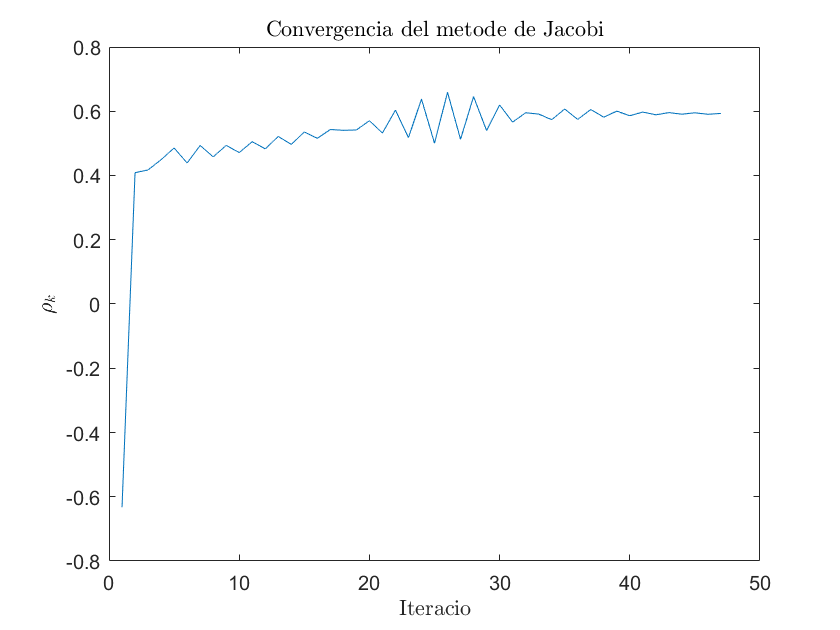


s = size(rhok);
figure(1)
plot(1:s(2), rhok)
title('Convergencia del metode de Jacobi', 'Interpreter','latex')
xlabel('Iteracio', 'Interpreter','latex')
ylabel('$\rho_k$', 'Interpreter','latex')


% Podem veure com el metode convergeix :)

**Resposta ** Gràfica explicativa.